# NYC Taxi Trip Data Mining

tbl=readtable('clean_yellow_sample_2016_06.csv');
summary(tbl)


Variables:

    pickup_longitude: 1029593×1 double
        Values:

            最小值    -115.17           
            中位数    -73.981           
            最大值    -56.643           

    pickup_latitude: 1029593×1 double
        Values:

            最小值    33.611           
            中位数    40.755           
            最大值    51.098           

    dropoff_longitude: 1029593×1 double
        Values:

            最小值    -115.18            
            中位数    -73.979            
            最大值     106.25            

    dropoff_latitude: 1029593×1 double
        Values:

            最小值    33.895            
            中位数    40.755            
            最大值    50.312            

    trip_distance: 1029593×1 double
        Values:

            最小值    0.01           
            中位数    1.72           
            最大值     500           

    passenger_count: 1029593×1 double
    

latitude range [40.6,40.85]

longitude range [-74.05,-73.75]

## Taxi Trip Person Frequency

The area where most trips originate is devided into 200*200 girded blocks.

Z is normalized to be within the range (0,1). Higher z means more people taking a taxi from the block.

yedges=linspace(40.6,40.85,50);%latitude
xedges=linspace(-74.05,-73.75,50);%longitude
[tab,I,J]=hist3d(tbl.pickup_longitude,tbl.pickup_latitude,tbl.passenger_count,xedges,yedges);
csvwrite('50grid.csv'.tab)
yedges=linspace(40.6,40.85,100);%latitude
xedges=linspace(-74.05,-73.75,100);%longitude
[tab2,I,J]=hist3d(tbl.pickup_longitude,tbl.pickup_latitude,tbl.passenger_count,xedges,yedges);
csvwrite('100grid.csv',tab2)
%{
area=abs((yedges(2)-yedges(1))*(xedges(2)-xedges(1)));
tab=tab/area;%z is now averaging on block area.
tab=tab/max(max(tab));%normalize Z value
C=tab;C(C<eps)=NaN; 
figure
surf(xedges,yedges,tab,C,'linestyle','none')
colorbar
colormap jet
xlabel('longitude')
ylabel('latitude')
zlabel('Frequency')
title('Distribuion of Number of Origins of Trips','FontSize',12)
%}

 MATLAB 运算符异常。

未定义与 'double' 类型的输入参数相对应的函数 'write'。

出错 writetable (line 121)
write(a,filename,varargin{:})

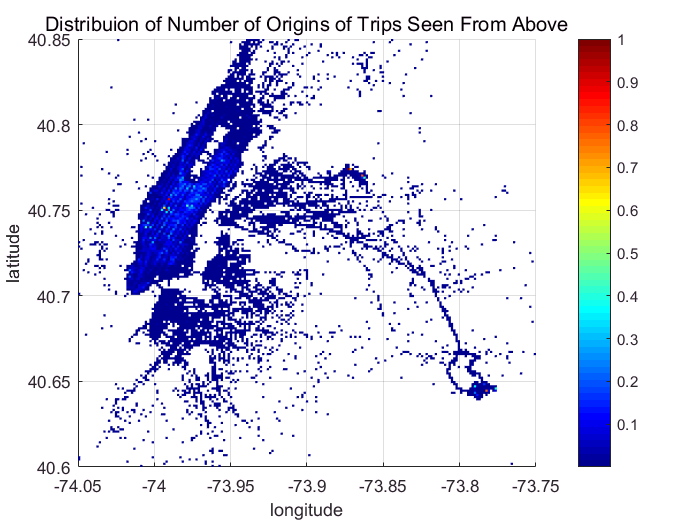

surf(xedges,yedges,tab,C,'linestyle','none')
colorbar
xlabel('longitude')
ylabel('latitude')
zlabel('Frequency')
title('Distribuion of Number of Origins of Trips Seen From Above','FontSize',12)
view(2)

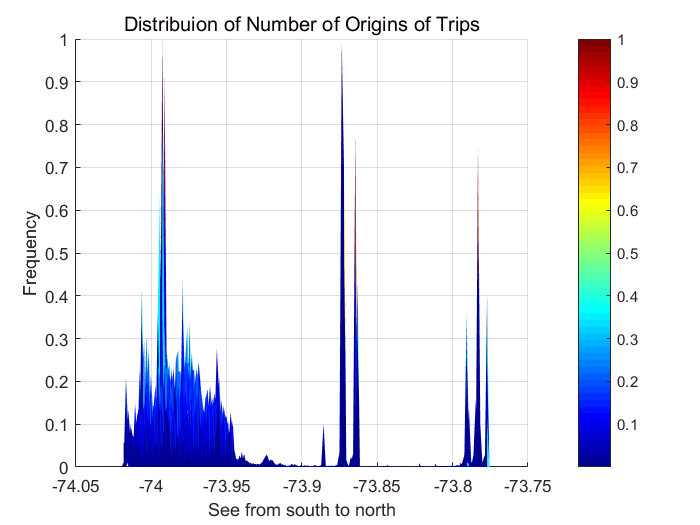


surf(xedges,yedges,tab,C,'linestyle','none')
colorbar
view([0 -1 0])
xlabel('See from south to north')
zlabel('Frequency')
title('Distribuion of Number of Origins of Trips','FontSize',12)

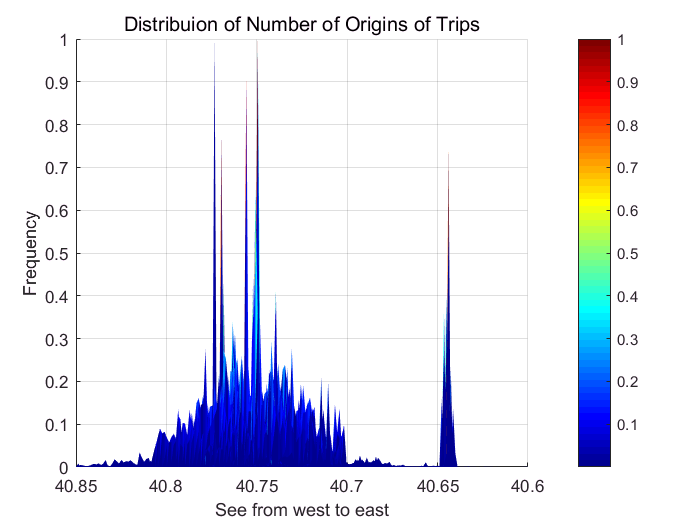


surf(xedges,yedges,tab,C,'linestyle','none')
colorbar
view([-1 0 0])
ylabel('See from west to east')
zlabel('Frequency')
title('Distribuion of Number of Origins of Trips','FontSIze',12)

## Now we take a look at the place where most (most means above median) of the trips originate. We find the busiest place in NYC!

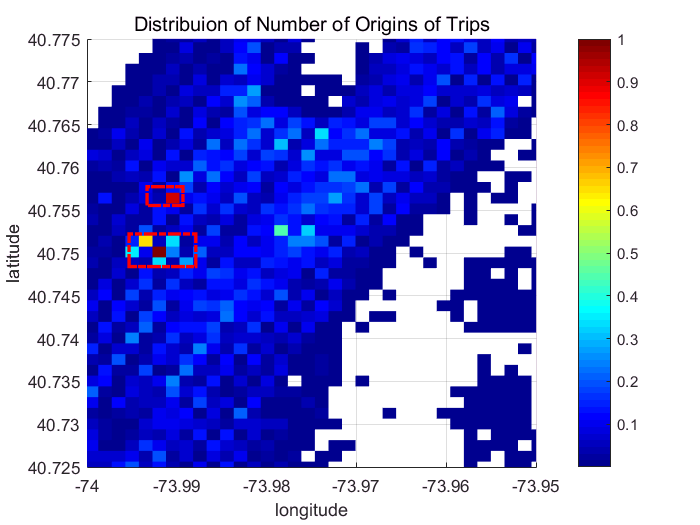

tab(tab<median(tab(:)))=NaN;
C=tab;C(C==0)=NaN; %colormap
surf(xedges,yedges,tab,C,'linestyle','none')
colorbar
xlabel('longitude')
ylabel('latitude')
zlabel('Frequency')
title('Distribuion of Number of Origins of Trips','FontSize',12)
view(2)
xlim([-74,-73.95])
ylim([40.725,40.775])

annotation('rectangle',...
    [0.210039548022599 0.608591885441527 0.0512598870056497 0.0357995226730309],...
    'Color',[1 0 0],...
    'LineWidth',2,...
    'LineStyle','-.');
annotation('rectangle',...
    [0.184375 0.492227979274611 0.0953125 0.0621761658031088],'Color',[1 0 0],...
    'LineWidth',2,...
    'LineStyle','-.');

## The busiest are is -74<lat<-73.99 and 40.7485<lon<40.7495

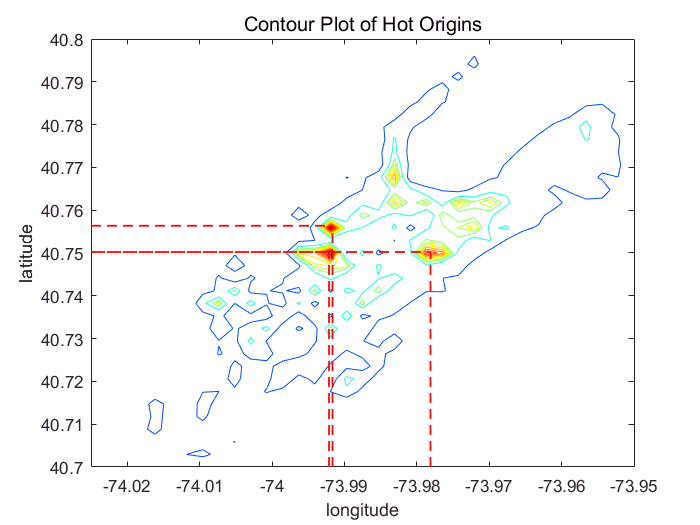


%yedges=linspace(40.7485,40.7495,10);%latitude
%xedges=linspace(-74,-73.99,10);%longitude
yedges=linspace(40.7,40.8,35);%latitude
xedges=linspace(-74.025,-73.95,35);%longitude
[tab,I,J]=hist3d(tbl.pickup_longitude,tbl.pickup_latitude,tbl.passenger_count,xedges,yedges);
area=abs((yedges(2)-yedges(1))*(xedges(2)-xedges(1)));
tab=tab/area;%z is now averaging on block area.
tab=tab/max(max(tab));%normalize Z value
[X,Y]=meshgrid(xedges,yedges);
figure
contour(X,Y,tab,[0 0.2 0.4 0.5:0.05:1]);
colormap jet
title('Contour Plot of Hot Origins','FontSize',12)
xlabel('longitude')
ylabel('latitude')
annotation('line',[0.47 0.133],...
    [0.52 0.52],'Color',[1 0 0],'LineWidth',1,...
    'LineStyle','--');
annotation('line',[0.47 0.47],...
    [0.11 0.52],'Color',[1 0 0],'LineWidth',1,...
    'LineStyle','--');

annotation('line',[0.475 0.475],...
    [0.11 0.57],'Color',[1 0 0],'LineWidth',1,...
    'LineStyle','--');
annotation('line',[0.13 0.475],...
    [0.57 0.57],'Color',[1 0 0],'LineWidth',1,...
    'LineStyle','--');

annotation('line',[0.13 0.615],...
    [0.52 0.52],'Color',[1 0 0],'LineWidth',1,...
    'LineStyle','--');
annotation('line',[0.615 0.615],...
    [0.11 0.52],'Color',[1 0 0],'LineWidth',1,...
    'LineStyle','--');